

lead_1_log_1m = load("Lead_1_logarithmic_1m.mat", "out")

lead_1_log_1m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


lead_1_unopt_1m = load("Lead_1_unoptimized_1m.mat", "out")

lead_1_unopt_1m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


lead_1_log_01m = load("Lead_1_logarithmic_01m.mat", "out")

lead_1_log_01m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


lead_1_unopt_01m = load("Lead_1_unoptimized_01m.mat", "out")

lead_1_unopt_01m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


asd = stepinfo(lead_1_log_1m.out.last_test,lead_log_1m.out.tout , 1)

asd = struct with fields:
        RiseTime: 0.2205
    SettlingTime: 0.4530
     SettlingMin: 0.9001
     SettlingMax: 1.0201
       Overshoot: 2.0129
      Undershoot: 0
            Peak: 1.0201
        PeakTime: 0.4444


asd = stepinfo(lead_1_unopt_1m.out.last_test,lead_unopt_1m.out.tout, 1 )

asd = struct with fields:
        RiseTime: 0.2338
    SettlingTime: 0.9174
     SettlingMin: 0.9002
     SettlingMax: 0.9997
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9997
        PeakTime: 4


asd = stepinfo(lead_1_log_01m.out.last_test,lead_log_1m.out.tout, 0.1 )

asd = struct with fields:
        RiseTime: 0.1540
    SettlingTime: 0.3053
     SettlingMin: 0.0900
     SettlingMax: 0.1020
       Overshoot: 2.0012
      Undershoot: 0
            Peak: 0.1020
        PeakTime: 0.3038


asd = stepinfo(lead_1_unopt_01m.out.last_test,lead_unopt_1m.out.tout, 0.1 )

asd = struct with fields:
        RiseTime: 0.1540
    SettlingTime: 0.3053
     SettlingMin: 0.0900
     SettlingMax: 0.1020
       Overshoot: 2.0012
      Undershoot: 0
            Peak: 0.1020
        PeakTime: 0.3038




lead_2_log_1m = load("Lead_2_logarithmic_1m.mat", "out")

lead_2_log_1m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]





lead_2_unopt_1m = load("Lead_2_unoptimized_1m.mat", "out")

lead_2_unopt_1m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


lead_2_log_01m = load("Lead_2_logarithmic_01m.mat", "out")

lead_2_log_01m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]


lead_2_unopt_01m = load("Lead_2_unoptimized_01m.mat", "out")

lead_2_unopt_01m = struct with fields:
    out: [1×1 Simulink.SimulationOutput]



hold on

hold on

legend_title =  ["Lead 1: Unoptimized ","PI-Lead 1: Series Form" "PI-Lead 1: Ideal Form ","PI-Lead 4 " ,"Lead 1 ","Lead 2 " ]

legend_title = 1×6 string array
    "Lead 1: Unoptimized "    "PI-Lead 1: Series Form"    "PI-Lead 1: Ideal Form "    "PI-Lead 4 "    "Lead 1 "    "Lead 2 "


plot(out.tout, out.last_test) %% bbens 1
%plot(lead_2_unopt_01m.out.tout, lead_2_log_01m.out.last_test) %% henriks 2

plot(lead_1_log_01m.out.tout, lead_2_log_01m.out.last_test) %% bbens 1
%plot(lead_1_unopt_01m.out.tout, lead_2_log_01m.out.last_test) %% henriks 2

legendCell = legend_title;
ylabel('Displacement [m]')
xlabel('Time  [s]')
leg = legend('show');
legend(legendCell)

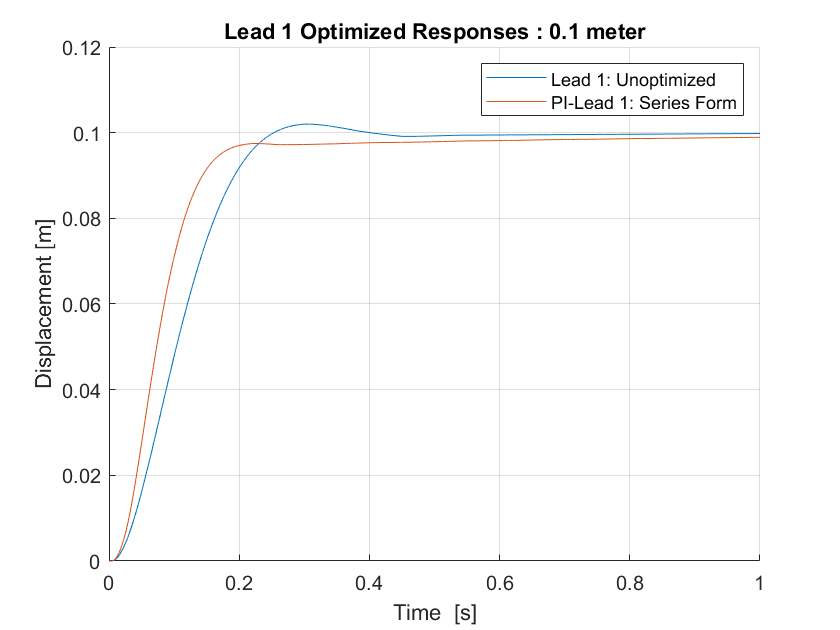

title("Lead 1 Optimized Responses : 0.1 meter")
ylim([0, .12])
xlim([0, 1])
grid on


hold off







%Fake line



e = load("pid_1_1m.mat", "out")
f = load("pid_2_1m.mat", "out")



legend_title =  ["PI-Lead 1: Linear ","PI-Lead 1: Series Form" "PI-Lead 1: Ideal Form ","PI-Lead 4 " ,"Lead 1 ","Lead 2 " ]

hold on
plot(e.out.tout,e.out.linear_pos)
plot(a.out.tout, a.out.last_test) %% bbens 1
plot(d.out.tout, d.out.last_test.Data) %% henriks 2
legendCell = legend_title;
ylabel('Displacement [m]')
xlabel('Time  [s]')
leg = legend('show');
legend(legendCell)
title("PI-Lead 1 Optimized Responses : 1 meter")
ylim([0, 1.2])
xlim([0, 1])
grid on



hold off

figure()
hold on
legend_title =  ["PI-Lead 2: Linear ","PI-Lead 2: Series Form" "PI-Lead 2: Ideal Form ","PI-Lead 4 " ,"Lead 1 ","Lead 2 " ]
plot(f.out.tout,f.out.linear_pos)
plot(b.out.tout, b.out.last_test) %% bens 2
plot(c.out.tout, c.out.last_test.Data) %% henriks 1
legendCell = legend_title;
ylabel('Displacement [m]')
xlabel('Time  [s]')
leg = legend('show');
legend(legendCell)
title("PI-Lead 2 Optimized Responses : 1 meter")
ylim([0, 1.2])
xlim([0, 1.2])
grid on

hold off





linear_data = linear_results(2:8, :);

hold on
plot(linear_results(1, :), linear_data)

legendCell = legend_title;
xlabel('Displacement [m]')
ylabel('Time  [s]')
leg = legend('show');
legend(legendCell)
title("PI-Lead 2 Logarithmic Algorithm: 1st Iteration")
hold off
grid on
ylim([0, 1.3])
xlim([0, 2])


nexttile



hold on
plot(linear_results(1, :), linear_data)
legend_title =  ["PI-Lead 1 ","PI-Lead 2" "PI-Lead 3 ","PI-Lead 4 " ,"Lead 1 ","Lead 2 " ]

legendCell = legend_title;
xlabel('Displacement [m]')
ylabel('Time  [s]')
leg = legend('show');
legend(legendCell)
title("Linear Step Response : 1 meter")
hold off
grid on
ylim([0, 0.12])
xlim([0, 2])

% 
% hold on
% plot(T_sample_comparison_001{2}.Values)
% plot(T_sample_comparison_01{2}.Values)
% legend_title =  ["T_{sample} - 1 ms ", "T_{sample} - 10 ms "]
% legendCell = legend_title;
% xlabel('Displacement [m]')
% ylabel('Time  [s]')
% leg = legend('show');
% legend(legendCell)
% title("Displacement over Sample Time")
% hold off
% grid on
% xlim([0, 1])
% 
% 